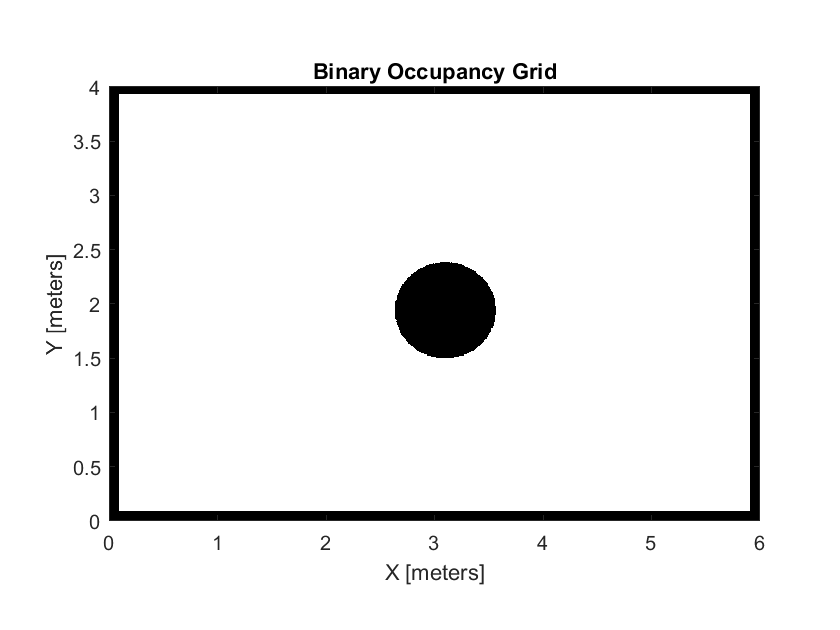

map1 = imread('map2.pbm');
map = binaryOccupancyMap(map1, 200); 
show(map)


%set the Visualizer2D parameters 
viz = Visualizer2D;
viz.robotRadius = 0.25; 
viz.showTrajectory = true; 
viz.mapName = 'map'; 
viz.hasWaypoints = true;

% create robot 
R = 0.2;
W = viz.robotRadius * 2; 
robot = [R W];

% set the obstacle sensors parameters 
lidar = LidarSensor;
lidar.scanAngles = [-pi/3,-pi/9,0,pi/9,pi/3]; 
lidar.maxRange = 0.6; 
attachLidarSensor(viz,lidar);
waypoints = [5 3.5];

sampleTime = 0.01;
step = 1;
curPose = [0.7; 1; -pi/2]; 
pose = curPose;

while((abs(waypoints(1)-curPose(1))>.1)||(abs(curPose(2)-waypoints(2))>.1)) 
    next_position = [0;0;0];
    pose = [pose next_position]; % concatenate next pose to the pose matrix

    % calculate the direction to target (degrees to understand easier) 
    targetDir = rad2deg(atan2(waypoints(2)-curPose(2),... 
        waypoints(1)-curPose(1)) - curPose(3));
    
    % make the direction circulat in -180 - 180 degrees 
    if targetDir > 180
        targetDir = targetDir - 360; 
    elseif targetDir < -180
        targetDir = 360 + targetDir;
    end
    
    % normalize dir -0.5 - 0.5 for ANN
    % positive --> turn left
    % negative --> turn right
    targetDir = ((targetDir+180)/(2*180)) - 0.5;
    
    % inputs from sensor
    ranges = (lidar(curPose) - viz.robotRadius); % inputs in range 0 - 0.25m
    % normalize to 0.1 - 1 for ANN 
    rangesN = (ranges+0.1)/0.4;
    
    % create ANN
    % inputs matrix --> [dir, CC, CR, CL, CRR, CLL] 
    inputs = [targetDir, 1/rangesN(3), 1/rangesN(2),...
    1/rangesN(4), 1/rangesN(1), 1/rangesN(5)];
    
    % change NaN inputs to 0 
    inputs (isnan(inputs)) = 0;
    
    % ANN
    weights = [-0.9, -0.15, 0, 0.35, 0, 0.5; % left wheel
    0.9, -0.15, 0.35, 0, 0.5, 0]; % right wheel
    bias = 0.2;
    activation = (weights * inputs.') + bias; leftW = activation(1)*30;
    rightW = activation(2)*30;
    
    % calc FK
    [v, y, w] = FK(robot,leftW,rightW);
    
    % calculate the velocity of the robot relative to the map 
    velocity = rtm([v; y; w], curPose);
    
    % calculate next pose
    pose(:,step+1) = curPose + velocity * sampleTime;
    
    % move toward waypoint viz(pose(:,step+1), waypoints, ranges)
    
    % iterate the counter and current pose variable 
    step = step + 1;
    curPose = pose(:,step);
end


function [v, y, w] = FK(robot, LW, RW)
    y = 0; % zero lateral velocity (for rtm) 
    v = 0.5 * robot(1) * (LW + RW);
    w = (RW - LW) * robot(1)/robot(2);
end

function velocity = rtm(V, pose) 
    angle = pose(3);
    velocity = [cos(angle) -sin(angle) 0; sin(angle) cos(angle) 0; 0 0 1]*V;
end

